# The Airy Disk of a diffraction limited system

The **Airy Disk** describes the blur arising from an ideal (diffraction-limited) uniformly illuminated, circular aperture. It is named for the astronomer [George Biddell Airy](https://en.wikipedia.org/wiki/Airy_disk).  This script exposes the code used to calculate and plot the Airy disk for diffraction limited optics. The same code will run with the same basic plots if you use the wavefront oi, oiCreate('wvf').

**See also**

  dlMTF, oiCreate; oiCompute, ieShape, ieDrawShape

Copyright ImagEval Consultants, LLC, 2010.

ieInit

## Establish an OI with diffraction limited optics

It is straightforward to calculate the diffraction limited PSF using these functions.  We explain what they do, below.

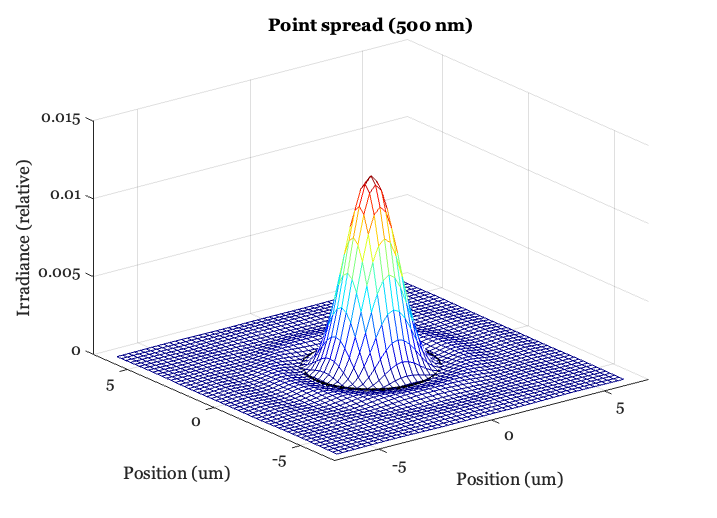

% Default optics is diffraction limited
oi = oiCreate('diffraction limited');          % If you use 'wvf', the same ideas work
oiPlot(oi,'psf',[],500,'um','airydisk',true);  % Show the Airy disk as the black circle
set(gca,'xlim',[-7 7],'ylim',[-7 7]);

## The computation

We select the wavelength and spatial sampling for the plot. For diffraction limited optics the only important parameter is the f/#.

optics = oiGet(oi,'optics');

nSamp    = 25;  % How many frequency samples?
thisWave = 500; % nm

% Spatial sampling units
spatialUnits = 'um';

We find the frequency samples that the diffraction limited lens supports.  We call this the dlFSsupport for this wavelength.  This defienes which frequency samples we will use.

clear fSupport
val = opticsGet(optics,'dlFSupport',thisWave, spatialUnits, nSamp);
[fSupport(:,:,1),fSupport(:,:,2)] = meshgrid(val{1},val{2});

To make a smooth PSF plot, we oversample the frequency. Because there are two spatial samples at the highest spatial frequency, the spatial sample spacing will 1/(2*peakF)

**Remember: ** We specified the spatialUnits as microns (above), so the frequency is cycles/micron. When we calculate the spacing, it is in microns.

fSupport = fSupport*4;     % Increase the spatial frequency sampling
peakF = max(fSupport(:));
deltaSpace = 1/(2*peakF);  % Sample spacing in microns

## Calculate the MTF (dlMTF)

The diffraction-limited MTF (dlMTF) function calculates the diffraction limited MTF

otf = dlMTF(oi,fSupport,thisWave,spatialUnits);

% The PSF is a Fourier transform away from the otf 
psf = fftshift(ifft2(otf));

% Using deltaSpace, make the spatial support for the PSF
clear sSupport
samp = (-nSamp:(nSamp-1));
[X,Y] = meshgrid(samp,samp);
sSupport(:,:,1) = X*deltaSpace;
sSupport(:,:,2) = Y*deltaSpace;

Here is the key step for calculating the Airy disk.  It is based on the formula from Lord Airy!

fNumber = opticsGet(optics,'fNumber');
radius = (2.44*fNumber*thisWave*10^-9)/2 * ieUnitScaleFactor(spatialUnits);

The rest is plotting. 

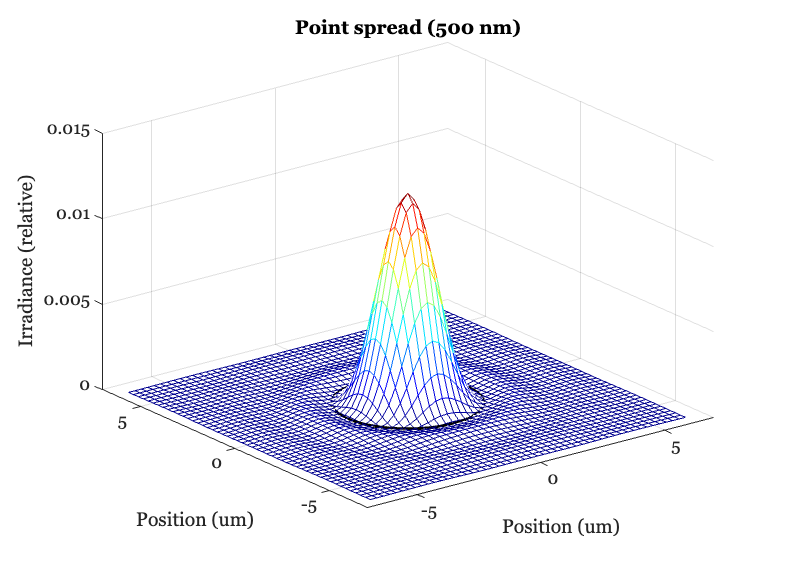

x = sSupport(:,:,1); y = sSupport(:,:,2);
ieNewGraphWin;
mesh(x,y,psf);
colormap(jet(64))

% Draw a circle at the first zero crossing (Airy disk)
nCircleSamples = 200;
[adX,adY,adZ] = ieShape('circle',nCircleSamples,radius);

% Lift the Airy disk ring up a bit so we can see it on the graph
ringZ = max(psf(:))*1e-3;
hold on; p = plot3(adX,adY,adZ + ringZ,'k-');
set(gca,'xlim',[-7 7],'ylim',[-7 7]);

set(p,'linewidth',3); hold off;
xlabel('Position (um)'); ylabel('Position (um)');
zlabel('Irradiance (relative)');
title(sprintf('Point spread (%.0f nm)',thisWave));